# ADXL


filename = "output_adxl_data.csv"

filename = "output_adxl_data.csv"

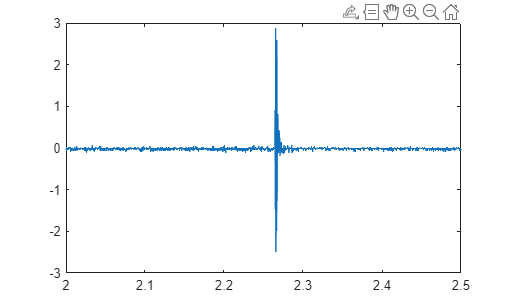


data = readmatrix(filename);

t = data(:,1);
x = data(:,2);
y = data(:,3);
z = data(:,4);

module = sqrt(x.^2 + y.^2 + z.^2);

figure;
plot(t, x);


Fs = 1/(t(2)-t(1)); % sampling frequency

%% ===== COMPUTE CWT =====
% 'amor' = Morlet wavelet (nejlepší pro vibrace)
% increase frequency resolution by specifying more voices per octave
voicesPerOctave = 48; % increase from default (e.g., 12) for finer freq resolution
[cfs, F] = cwt(x, Fs, 'amor', 'VoicesPerOctave', voicesPerOctave);

% převod na dB
C_dB = 20*log10(abs(cfs) + 1e-12);

set(0,'DefaultFigureVisible','on')

%% ===== PLOT =====
figure;
imagesc(t, F, C_dB);
axis xy;

set(gca, 'YScale', 'log');   % log frekvence

xlabel('Čas [s]');
ylabel('Frekvence [Hz]');
set(gca, 'TickDir', 'out');

colormap(jet);
cb = colorbar;
cb.Label.String = 'Amplituda [dB re 1g]';

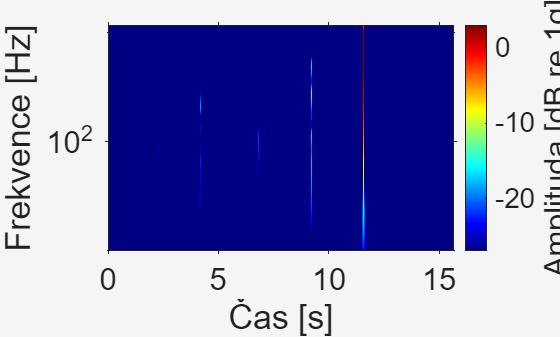

cb.Label.FontSize = 23;

% dynamický rozsah
clim([max(C_dB(:))-40, max(C_dB(:))-10]);

% omezení frekvenčního rozsahu (upravit dle potřeby)
ylim([10 max(F)]);

set(gca, 'FontSize', 23);

## ADC


filename = "output_adc0_data.csv"

filename = "output_adc0_data.csv"

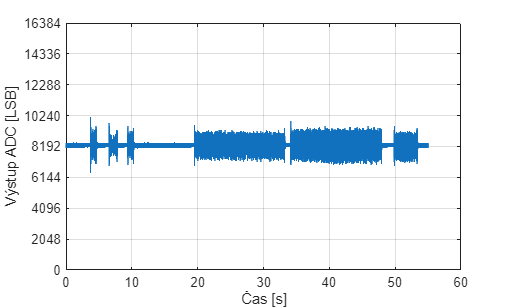


data = readmatrix(filename);

t = data(:,1);
ch1 = data(:,2);
ch2 = data(:,3);

module = ch1;

figure;
plot(t, module);
xlabel("Čas [s]");
ylabel("Výstup ADC [LSB]");
ylim([0 16384]);
yticks((1:2048:18000) - 1);
grid on


Fs = 1/(t(2)-t(1)); % sampling frequency

%% ===== COMPUTE CWT =====
% 'amor' = Morlet wavelet (nejlepší pro vibrace)
voicesPerOctave = 24; % increase from default (e.g., 12) for finer freq resolution
[cfs, F] = cwt(module, Fs, 'amor', 'VoicesPerOctave', voicesPerOctave);

% převod na dB
C_dB = 20*log10(abs(cfs) + 1e-12);

set(0,'DefaultFigureVisible','on')

%% ===== PLOT =====
figure;
imagesc(t, F, C_dB);
axis xy;

set(gca, 'YScale', 'log');   % log frekvence

xlabel('Čas [s]');
ylabel('Frekvence [Hz]');
set(gca, 'TickDir', 'out');

colormap(jet);
cb = colorbar;
cb.Label.String = 'Amplituda [dB re 1g]';

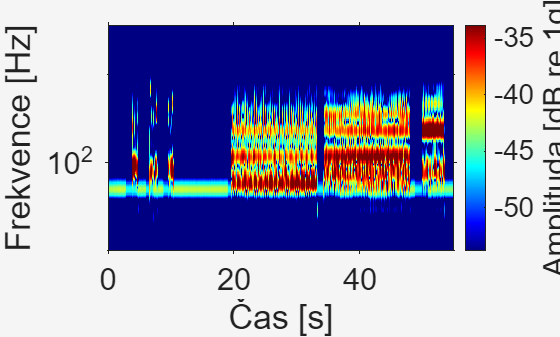

cb.Label.FontSize = 23;

% dynamický rozsah
clim([max(C_dB(:))-30, max(C_dB(:))-10]);

% omezení frekvenčního rozsahu (upravit dle potřeby)
ylim([10 max(F)]);

set(gca, 'FontSize', 23);

## BNO


filename = "output_bno_data.csv"

filename = "output_bno_data.csv"

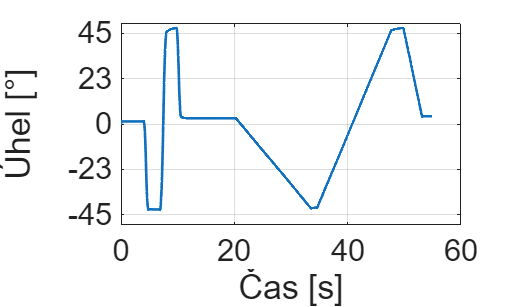


data = readmatrix(filename);

t = data(:,1);
eul_h = data(:,11);
eul_r = data(:,12);
eul_p = data(:,13);

figure;
plot(t, eul_r, LineWidth=2);
xlabel("Čas [s]","FontSize",28);
ylabel("Úhel [°]", "FontSize",28);
yticks([-67.5 -45 -22.5 0 22.5 45 67.5]);

grid on;

set(gca, 'FontSize', 23);